%% Program Intitialization
clear;
close all;
clc;
format long g;
%% 
% This MATLAB script is to simulate and plot the relationship between relay
% node density (# of relay nodes / sq. m) and the transmission capacity of
% the D2D network (in overlay mode)

% This is the code for CASE 2, where we consider that D2D comms communicating without
% relay node appearing in overlap region

lambda_1 = 0.0003; % D2D density in the area
lambda_2 = 0.0004; % RN density in the area
P_1 = 0.031622; % in Watts ,15 dbm, D2D transmission power
P_2 = 0.031622; % in Watts ,15 dbm, relay node transmission power


T_1 = 1.58489; % 2 db, D2D SIR threshold
T_2 = 1.58489; % 2 db, RN SIR threshold



alpha = 4; % Path loss exponent
R = 35; % D2D link distance


% Values defined in the paper
S = (2*pi/3 - sqrt(3)/2)*R^2;
Pr_e = 1 - exp(-1*lambda_2*S);
A = (4*pi - 36*sqrt(3) + 64)/(12*pi - 9*sqrt(3));
E = A*R;
C_alpha = pi*gamma(1 + 2/alpha)*gamma(1-(2/alpha));


% SIR threshold probability
sir_d_to_d_ov2(lambda_1, Pr_e, C_alpha, T_1, alpha, R, P_2, P_1)

ans =          0.101966693735243


sir_d_to_rn_ov2(lambda_1, Pr_e, C_alpha, T_2, alpha, E , P_2, P_1);
sir_rn_to_d_ov2(lambda_1, Pr_e, C_alpha, T_2, alpha, E , P_2, P_1);

transmission_capacity(lambda_1, Pr_e, C_alpha, T_1, T_2, alpha, R, E , P_2, P_1)

ans =        2.7038301057107e-05




% What we want
transmission_capacity(lambda_1, Pr_e, C_alpha, T_1, T_2, alpha, R, E , P_2, P_1); % transmission capacity in bps/Hz

rn_density = [0:0.000001:0.002];
tcs = zeros(1, length(rn_density));
for i = 1: length(rn_density)
    x = rn_density(i);
    p = 1 - exp(-1*x*S);
    tcs(i) = transmission_capacity(lambda_1, p, C_alpha, T_1, T_2, alpha, R, E , P_2, P_1);
end
tcs(1)

ans =       3.05900081205728e-05


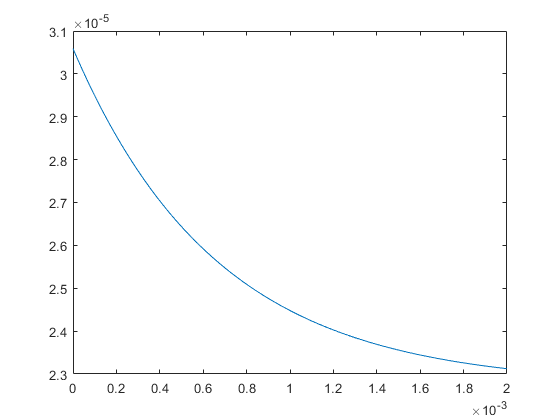

plot(rn_density, tcs);

dd_density = [0:0.000001:0.002];
tcs2 = zeros(1, length(rn_density));
for i = 1: length(dd_density)
    x = dd_density(i);
    tcs2(i) = transmission_capacity(x, Pr_e, C_alpha, T_1, T_2, alpha, R, E , P_2, P_1);
end

ans =      0


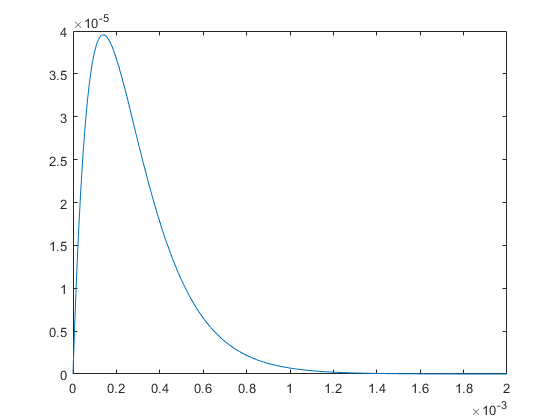

plot(dd_density,tcs2)

## Function definitions

function [prob_d_to_d_ov2] = sir_d_to_d_ov2(lambda_1, Pr_e, C_alpha, T_1, alpha, R , P_2, P_1)
    prob_d_to_d_ov2= exp(-lambda_1*C_alpha*(T_1^(2/alpha))*(R^2)*(1-(0.5*Pr_e)+(0.5*Pr_e*((P_2/P_1)^(2/alpha)))));
end
function [prob_d_to_rn_ov2] = sir_d_to_rn_ov2(lambda_1, Pr_e, C_alpha, T_2, alpha, E , P_2, P_1)
    prob_d_to_rn_ov2= exp(-lambda_1*C_alpha*(T_2^(2/alpha))*(E^2)*(1-(0.5*Pr_e)+(0.5*Pr_e*((P_2/P_1)^(2/alpha)))));
end

function [prob_rn_to_d_ov2] = sir_rn_to_d_ov2(lambda_1, Pr_e, C_alpha, T_2, alpha, E , P_2, P_1)
    prob_rn_to_d_ov2= exp(-lambda_1*C_alpha*(T_2^(2/alpha))*(E^2)*(((1- (0.5*Pr_e) *((P_1/P_2)^(2/alpha)))+(0.5*Pr_e))));
end

function [tc] = transmission_capacity(lambda_1, Pr_e, C_alpha, T_1, T_2, alpha, R, E , P_2, P_1)
    tc = ((lambda_1*(1-Pr_e)*sir_d_to_d_ov2(lambda_1, Pr_e, C_alpha, T_1, alpha, R , P_2, P_1))+(0.5*lambda_1*Pr_e*sir_d_to_rn_ov2(lambda_1, Pr_e, C_alpha, T_2, alpha, E , P_2, P_1)*sir_rn_to_d_ov2(lambda_1, Pr_e, C_alpha, T_2, alpha, E , P_2, P_1)));
end